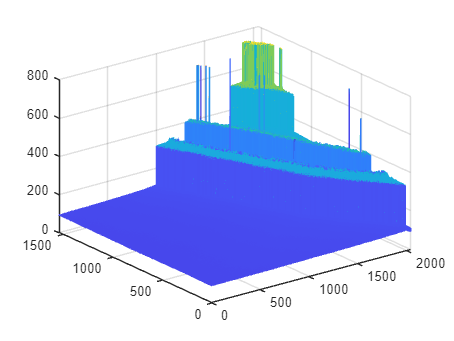

clc
clear
% 读取图像
img = imread('test.png');
img_double = double(img); % 转换为双精度，范围0-255

% 加载厚度对应的RGB数据（假设文件thickness_rgb.mat中包含变量thickness_rgb）
load('rm_f.mat');
ref_rgb = double(rgbmatrix(:,1:1000)'); % 确保参考数据为双精度，范围0-255

% 预处理图像数据
[M, N, ~] = size(img_double);
pixels = reshape(img_double, [], 3); % 转换为M*N x3矩阵

% 使用knnsearch进行最近邻匹配（优化计算）
height_indices = knnsearch(ref_rgb, pixels);

% 生成高度图
height_maps = reshape(height_indices, M, N, []);
mesh(height_maps);

% mat = zeros(M, N);
% for i = 1:M
%     i
%     for j = 1:N
%         u = coordinate(mat,i,j-1);
%         d = coordinate(mat,i-1,j);
%         ud = coordinate(mat,i-1,j-1);
%         mid = double(nanmean([u,d,ud]));
%         if isnan(mid)
%             mid = 0;
%         end
%         height_map = height_maps(i,j,:);
%         mat(i,j) = knnsearch(height_map(:), mid);
%     end
% end

% function [co] = coordinate(matrix, row, col)
%     siz = size(matrix);
%     if row>0 && row< siz(1) && col>0 && col<siz(2)
%         co = matrix(row,col);
%     else
%         co = NaN;
%     end
% end